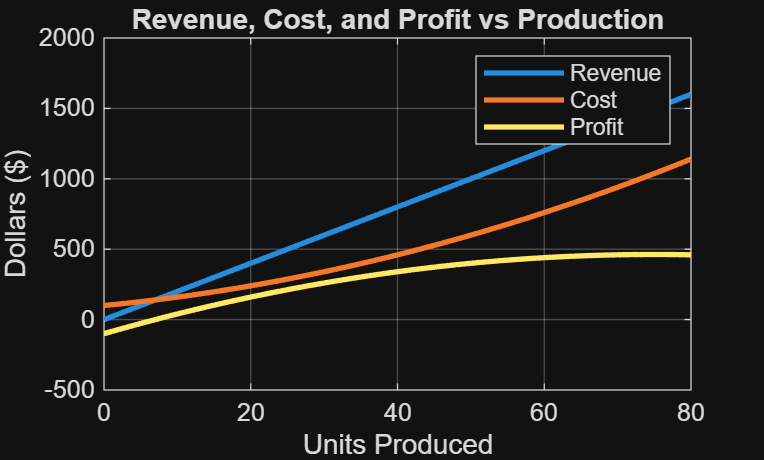

% Zulaikha Khan 
% ES 115 Engineering Computer Applications 
% Module 6 Project: Profit vs Production 
% Instructor: Lynroy Grant 
% March 28, 2026 
 
clear; clc; close all; 
 
% ---------------------------- 
% Define production values 
x = 0:1:80; 
 
% ---------------------------- 
% Choose realistic parameters 
p = 20; % revenue per unit 
a = 0.1; % quadratic cost factor 
b = 5; % linear cost 
c = 100; % fixed cost 
 
% ---------------------------- 
% Define functions 
R = p*x; % Revenue 
C = a*x.^2 + b*x + c; % Cost 
P = R - C; % Profit 
 
% ---------------------------- 
% Plot all three 
figure; 
plot(x, R, 'LineWidth', 2); hold on; 
plot(x, C, 'LineWidth', 2); 
plot(x, P, 'LineWidth', 2); 
 
title('Revenue, Cost, and Profit vs Production'); 
xlabel('Units Produced'); 
ylabel('Dollars ($)'); 
legend('Revenue', 'Cost', 'Profit'); 
grid on; 

 
% ---------------------------- 
% Find maximum profit 
[max_profit, idx] = max(P); 
x_max = x(idx); 
 
fprintf('Maximum profit of $%.2f occurs at x = %d units\n', max_profit, x_max); 

Maximum profit of $462.50 occurs at x = 75 units


 
% ---------------------------- 
% Find break-even points (P ≈ 0) 
index_be = find(abs(P) < 1); 
 
x_be = x(index_be); 
 
disp('Break-even point(s) (approximate x values):'); 

Break-even point(s) (approximate x values):


disp(x_be); 

     7

